## Material Properties

matboard_w = 812.8000

matboard_h = 1016

matboard_t = 1.2700

SA_board = 8.2580e+05

sigma_tens = 30

sigma_comp = 6

shear_strength = 4

youngs_modulus = 4000

poissons_ratio = 0.2000

shear_strength_glue = 2

x = 76

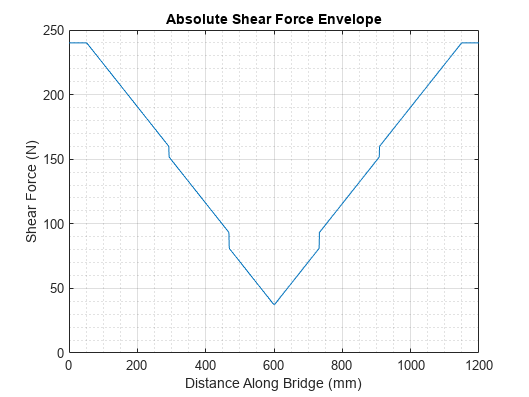

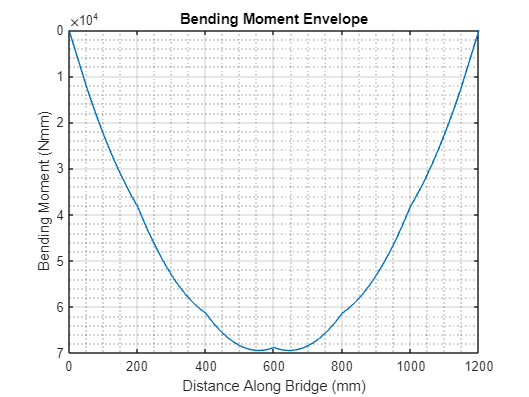

top_w = 100

bot_w = 80

height = 75

top_t = 1.2700

bot_t = 1.2700

side_t = 1.2700

glue_w = 5

glue_t = 1.2700

diaphragm_sep = 400

y_bar = 41.4311

I = 4.1835e+05

Q_cent = 6.1933e+03

Q_glue = 4.3439e+03

ans = 5.7832

ans = 6.8774

ans = 1.3988

ans = 0.2492

stress_top_plate = 3.5669

stress_side_flange = 20.7696

stress_varying_shear = 30.5759

stress_shear_buckle = 5.2566

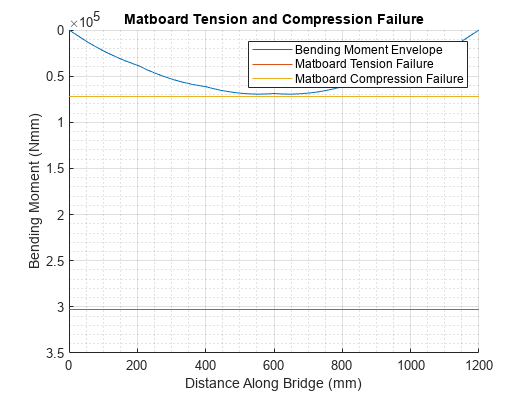

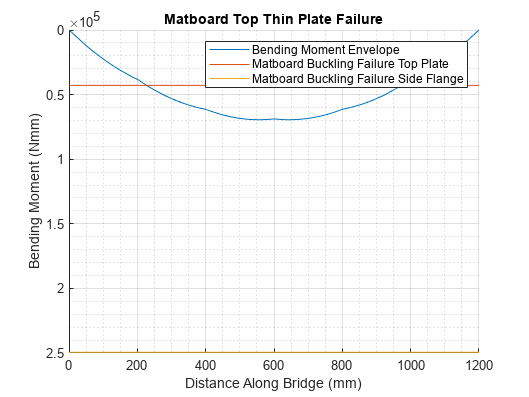

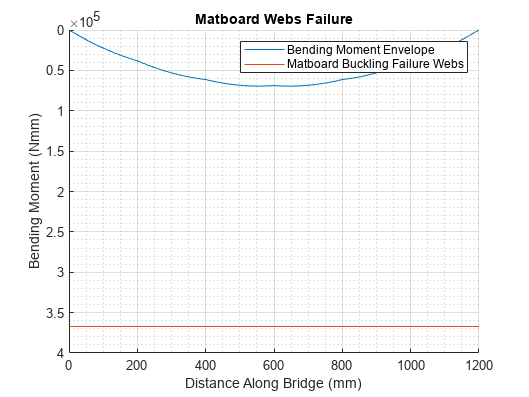

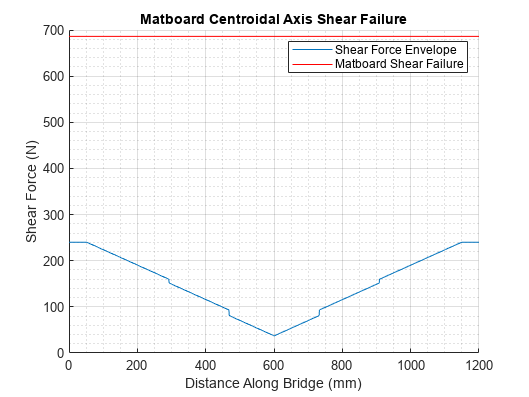

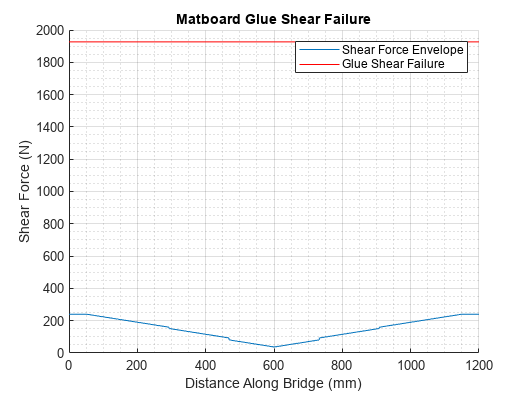

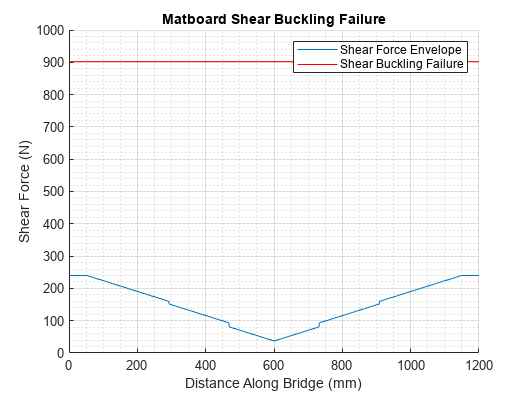

ans = 4.3621

ans = 1.0375

ans = 0.6168

ans = 3.5914

ans = 5.2871

ans = 2.8596

ans = 8.0257

ans = 3.7579

SA = 4.2209e+05

Surface_area_percent = 0.5111

close all;

clear;

% Matboard dimensions (from in to mm)
matboard_w = 32 * 25.4
matboard_h = 40 * 25.4
matboard_t = 0.05 * 25.4
SA_board = matboard_w * matboard_h

% Matboard properties
sigma_tens = 30
sigma_comp = 6
shear_strength = 4
youngs_modulus = 4000
poissons_ratio = 0.2

% Glue properties
shear_strength_glue = 2

## Moment and Shear Envelopes

L = 1200;  % Length of bridge
n = L+1;  % Number of points
P = 400;  % Total weight of train [N]
n_train = L-960+1;  % Number of train locations

lhs_dist = linspace(0, L, n);

% Offset by 1 because MALDLAB indexes with 1
% Offset by 1 more to shift cumsum one left
x_shear_start_locations = [52, 228, 392, 568, 732, 908] + 2;
x_train_loads = [-P/6, -P/6, -P/6, -P/6, -P/6, -P/6];
start_shear_all = (720-(0:1:n_train-1)')/3;  % Column vector of all possible starting shears
all_train_locations = zeros(n_train, n);

for i = 0:n_train-1
    all_train_locations(i+1, x_shear_start_locations+i) = x_train_loads;
end

% Each row is an SFD for each train location
all_shear = zeros(n_train, n);
all_shear(:,1) = start_shear_all;
all_shear = all_shear + all_train_locations;
all_shear = cumsum(all_shear, 2);

% Each row is a BMD for each train location
all_moment = cumsum(all_shear, 2);
all_moment = all_moment - start_shear_all;

x = 76  % Location of the train (not needed anymore)

% Shear and moment envelopes
shear_envelope = max(abs(all_shear));
moment_envelope = max(all_moment);

% Graphing Shear envelope
figure
plot(lhs_dist, shear_envelope)
grid on
grid minor
yline(0)
xlabel("Distance Along Bridge (mm)")
ylabel("Shear Force (N)")
title("Absolute Shear Force Envelope")

% Graphing moment envelope
figure
plot(lhs_dist, moment_envelope)
grid on
grid minor
set(gca, 'YDir', 'reverse')  % Flip y-axis
yline(0)
xlabel("Distance Along Bridge (mm)")
ylabel("Bending Moment (Nmm)")
title("Bending Moment Envelope")

% If querying x_shear and x_moment is required
% x_shear = all_shear(x+1,:);
% x_moment = all_moment(x+1,:);

## Bridge Geometry

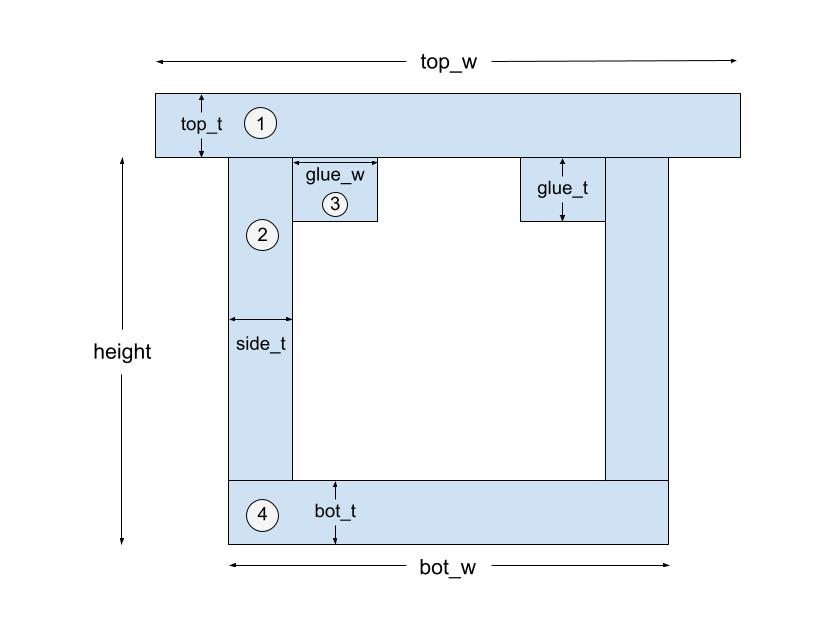

% Design 0 params followed by an underscore
top_w_ = 100;
bot_w_ = 80;
height_ = 75;
top_t_ = 1.27;
bot_t_ = 1.27;
side_t_ = 1.27;
glue_w_ = 5;  % Not including thickness of side
glue_t_ = 1.27;
diaphragm_sep_ = 400;

% New params (add, subtract, multiply old params)
top_w = top_w_ + 40
bot_w = bot_w_ - 5
height = height_ + 40
top_t = top_t_ * 2
bot_t = bot_t_
side_t = side_t_
glue_w = glue_w_
glue_t = glue_t_
diaphragm_sep = diaphragm_sep_ / 2

## Cross-Sectional Properties

% Calculate y bar, I, Q_glue, Q_cent

% Areas of split up sections
area_1 = top_t * top_w;
area_2 = (height-bot_t) * side_t;
area_3 = glue_w * glue_t;
area_4 = bot_t * bot_w;

% Height of each area's centroidal axis from base
y1 = height + top_t/2;
y2 = (height+bot_t) / 2;
y3 = height - glue_t/2;
y4 = bot_t/2;

% Local moment of inertias of each area
I1 = top_w*(top_t^3) / 12;
I2 = side_t*((height-bot_t)^3) / 12;
I3 = glue_w*(glue_t^3) / 12;
I4 = bot_w*(bot_t^3) / 12;

% Total area
tot_area = area_1 + 2*area_2 + 2*area_3 + area_4;

% Centroidal axis
y_bar = (area_1*y1 + 2*area_2*y2 + 2*area_3*y3 + area_4*y4) / tot_area

% Distance from global centroidal axis to local centoridal axes of areas
d1 = y1 - y_bar;
d2 = y2 - y_bar;
d3 = y3 - y_bar;
d4 = y_bar - y4;  % Order doesn't really matter but just for illustrative purposes

% Parallel axis theorem
sec1 = area_1*(d1^2) + I1;
sec2 = 2 * (area_2*(d2^2) + I2);
sec3 = 2 * (area_3*(d3^2) + I3);
sec4 = area_4*(d4^2) + I4;

% Moment of inertia
I = sec1 + sec2 + sec3 + sec4

% Q values
Q_cent = (bot_w-2*side_t)*bot_t*(y_bar-bot_t/2) + 2*y_bar*side_t*(y_bar/2)
Q_glue = area_1 * (height-y_bar + top_t/2)

## Non-Thin Plate Stresses

% Maximum abs(shear value) and abs(moment value)
[shear_max, shear_max_index] = max(shear_envelope);
[moment_max, moment_max_index] = max(moment_envelope);

% Largest tensile and compressive stress at every x
sigma_top_comp = moment_envelope*(height+top_t-y_bar) / I;
sigma_bot_tens = moment_envelope*y_bar / I;

% Largest shear stress at the centroidal axis at every x
T_cent = (shear_envelope*Q_cent) / (I*(2*side_t));

% Largest shear stress at glue joints at every x
T_glue = (shear_envelope*Q_glue) / (I*(2*glue_w));

% Max values for sigma_top_comp, sigma_bot_tens, T_cent, T_glue
max(sigma_top_comp)
max(sigma_bot_tens)
max(T_cent)
max(T_glue)

%{
%graph for sigma top
figure
hold on
plot(lhs_dist, sigma_top_comp)
plot(moment_max_index-1, sigma_top_comp(moment_max_index), "o")
xlabel("Distance Along Bridge (mm)")
ylabel("Compressive Stress (MPa)")
title("Maximum Flexural Compression at Top")
grid on
grid minor
legend("sigma\_top\_compress", "Max Value")

%graph for sigma bottom
figure
hold on
plot(lhs_dist, sigma_bot_tens)
plot(moment_max_index-1, sigma_bot_tens(moment_max_index), "o")
xlabel("Distance Along Bridge (mm)")
ylabel("Tensile Stress (MPa)")
grid on
grid minor
legend("sigma\_bot\_tens", "Max Value")
title("Maximum Flexural Tension at Bottom")

%graph for shear stress at center
figure
hold on
plot(lhs_dist, T_cent)
plot(shear_max_index-1, T_cent(shear_max_index), "o")
xlabel("Distance Along Bridge (mm)")
ylabel("Shear Stress (MPa)")
grid on
grid minor
legend("T\_cent","Max Value")
title("Shear Stress at Centroidal Axis")

%graph for shear stress at glue connection
figure
hold on
plot(lhs_dist,T_glue)
plot(shear_max_index-1, T_glue(shear_max_index),"o")
xlabel("Distance Along Bridge (mm)")
ylabel("Shear Stress (MPa)")
grid on
grid minor
legend("T\_glue", "Max Value")
title("Shear Stress at Glue Connection")
figure
%}

## Thin Plate Buckling

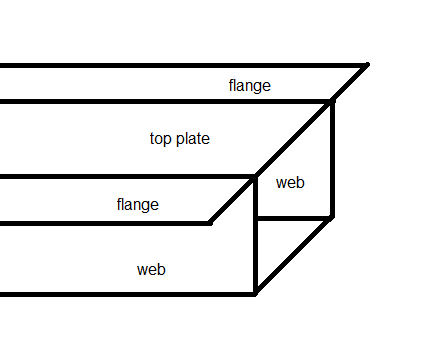

% Case 1: Bucking of the top plate due to flexural compression
t_top_plate = top_t;
b_in = bot_w - side_t;
stress_top_plate = (4*pi^2*youngs_modulus)/(12*(1-poissons_ratio^2)) * (t_top_plate/b_in)^2

% Case 2: Buckling of the flanges due to flexural compression
t_flange = top_t;
b_out = (top_w-bot_w)/2 + side_t/2;
stress_side_flange = (0.425*pi^2*youngs_modulus)/(12*(1-poissons_ratio^2)) * (t_flange/b_out)^2

% Case 3: Buckling of the webs due to varying flexural compression
t_web_flex = side_t;
y_top = height - glue_t/2 - y_bar;
stress_varying_shear = (6*pi^2*youngs_modulus)/(12*(1-poissons_ratio^2)) * (t_web_flex/y_top)^2

% Case 4: Shear buckling
t_web_shear = side_t;
h_web = height - glue_t/2 - bot_t/2;
stress_shear_buckle = (5*pi^2*youngs_modulus)/(12*(1-poissons_ratio^2)) * ((t_web_shear/h_web)^2 + (t_web_shear/diaphragm_sep)^2)

## Factor of Safety

% Flexural related
FOS_tension = sigma_tens ./ sigma_bot_tens;
FOS_comp = sigma_comp ./ sigma_top_comp;
FOS_flexbuck1 = stress_top_plate ./ sigma_top_comp;
FOS_flexbuck2 = stress_side_flange ./ sigma_top_comp;
FOS_flexbuck3 = stress_varying_shear ./ sigma_top_comp;

% Shear related FOS
FOS_shear = shear_strength ./ T_cent;
FOS_shear_glue = shear_strength_glue ./ T_glue;
FOS_shear_buck = stress_shear_buckle ./ T_cent;


## Shear Force Capacities + Bending Moment Capacities

% Flexural related capacities
M_fail_tens = FOS_tension .* moment_envelope;
M_fail_comp = FOS_comp .* moment_envelope;
M_fail_buck1 = FOS_flexbuck1 .* moment_envelope;
M_fail_buck2 = FOS_flexbuck2 .* moment_envelope;
M_fail_buck3 = FOS_flexbuck3 .* moment_envelope;

% Shear related capacities
V_fail_shear = FOS_shear .* shear_envelope;
V_fail_shear_glue = FOS_shear_glue .* shear_envelope;
V_fail_shear_buck = FOS_shear_buck .* shear_envelope;

% Matboard tension and compression failure
figure
hold on;
set(gca, 'YDir', 'reverse') 
plot(lhs_dist, moment_envelope)
plot(lhs_dist, M_fail_tens)
plot(lhs_dist, M_fail_comp)
xlabel("Distance Along Bridge (mm)")
ylabel("Bending Moment (Nmm)")
grid on
grid minor
title("Matboard Tension and Compression Failure")
legend("Bending Moment Envelope", "Matboard Tension Failure", "Matboard Compression Failure")
hold off;

% Matboard top thin plate failure
figure
hold on;
set(gca, 'YDir', 'reverse') 
plot(lhs_dist, moment_envelope)
plot(lhs_dist, M_fail_buck1)
plot(lhs_dist, M_fail_buck2)
xlabel("Distance Along Bridge (mm)")
ylabel("Bending Moment (Nmm)")
grid on
grid minor
title("Matboard Top Thin Plate Failure")
legend("Bending Moment Envelope", "Matboard Buckling Failure Top Plate", "Matboard Buckling Failure Side Flange")
hold off;

% Matboard webs failure
figure
hold on;
set(gca, 'YDir', 'reverse') 
plot(lhs_dist, moment_envelope)
plot(lhs_dist, M_fail_buck3)
xlabel("Distance Along Bridge (mm)")
ylabel("Bending Moment (Nmm)")
grid on
grid minor
title("Matboard Webs Failure")
legend("Bending Moment Envelope", "Matboard Buckling Failure Webs")
hold off;

% Matboard centroidal axis shear failure
figure
hold on
plot(lhs_dist, shear_envelope)
plot(lhs_dist, V_fail_shear, "r")
xlabel("Distance Along Bridge (mm)")
ylabel("Shear Force (N)")
grid on
grid minor
title("Matboard Centroidal Axis Shear Failure")
legend("Shear Force Envelope", "Matboard Shear Failure")
hold off

% Matboard glue shear failure
figure 
hold on 
plot(lhs_dist, shear_envelope)
plot(lhs_dist, V_fail_shear_glue, "r")
legend("Shear Force Envelope", "Glue Shear Failure")
xlabel("Distance Along Bridge (mm)")
ylabel("Shear Force (N)")
title("Matboard Glue Shear Failure")
grid on
grid minor
hold off

% Matboard shear buckling failure
figure 
hold on 
plot(lhs_dist, shear_envelope)
plot(lhs_dist, V_fail_shear_buck, "r")
legend("Shear Force Envelope", "Shear Buckling Failure")
xlabel("Distance Along Bridge (mm)")
ylabel("Shear Force (N)")
title("Matboard Shear Buckling Failure")
grid on
grid minor
hold off

## Summary of Minimum FOSs

min(FOS_tension)
min(FOS_comp)
min(FOS_flexbuck1)
min(FOS_flexbuck2)
min(FOS_flexbuck3)
min(FOS_shear)
min(FOS_shear_glue)
min(FOS_shear_buck)

## Surface Area (maybe a bit scuffed rn)

% Surface areas for each matboard area with stacking considered
SA1 = top_w * L * (top_t/top_t_);
SA2 = (height-bot_t) * L * (side_t/side_t_);
SA3 = glue_w * L * (glue_t/glue_t_);
SA4 = bot_w * L * (bot_t/bot_t_);

% Surface areas for each diaphragm
SAd = (bot_w-2*side_t) * (height-bot_t);  % Upper bound
extra = 0;  % Manually edit - extra diaphragms
num_diaphragms = (L/diaphragm_sep) + extra;

% Total surface area
SA = SA1 + 2*SA2 + 2*SA3 + SA4 + SAd*num_diaphragms

% Make sure to not exceed 0.8
Surface_area_percent = SA/SA_board
